# Aula 5 - Laboratório de Controle - 2021/1

##  Efeito dos ganhos do controlador PID

## Nome: Arthur Lorencini Bergamaschi

G=init(1,2)

G =
 
         144
  -----------------
  s^2 + 21.6 s + 36
 
Continuous-time transfer function.



## Atividade 1 - Avaliação do efeito do ganho proporcional Kp em regime e no transitório

Use o comando rlocus(G) ou rlocus(G,K) para obter k1 para UP=5% e k2 para UP=70%.

Escolher Tempo de modo que na figura 1 se tenha a resposta transitória e de regime.

Execute a seção a seguir e **mostre as figuras 1 e 2 ao professor. D**epois, responda as perguntas 1.1 a 1.5.

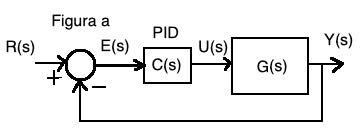

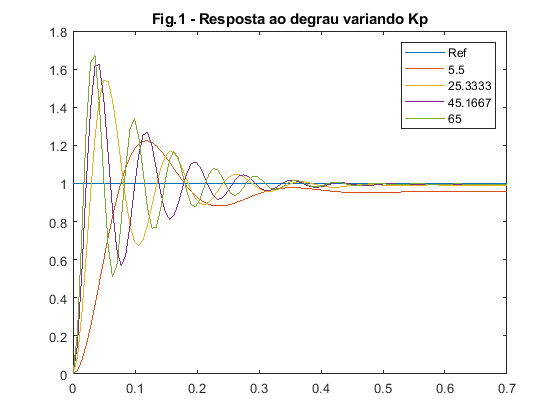

Tempo=0.7;
k1=5.5;
k2=65;
K=linspace(k1,k2,10);
Y=[];
C=pid(1,0,0);
t=linspace(0,Tempo,100)';
for i=1:length(K)
    C.Kp=K(i); 
    Gmf=feedback(C*G,1);
    y=step(Gmf,t); 
    S=stepinfo(y,t); 
    Erro(i,1)=100*abs(1-y(end)); 
    UP(i,1)=S.Overshoot; 
    tempo_est(i,1)=S.SettlingTime; 
    tempo_sub(i,1)=S.RiseTime;   
    IAE(i)=trapz(t,abs(1-y));
    Y=[Y y]; 
end

figure
plot(t,[ones(size(t)) Y(:,[1,4,7,10])]);title('Fig.1 - Resposta ao degrau variando Kp');
legend('Ref',num2str(K(1)),num2str(K(4)),num2str(K(7)),num2str(K(10)));

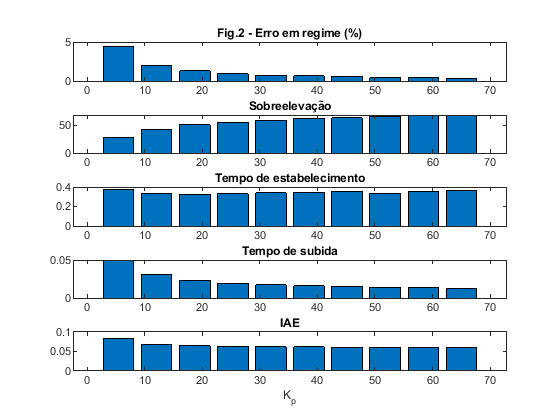


figure
subplot(5,1,1);bar(K,Erro);title('Fig.2 - Erro em regime (%)');
subplot(5,1,2);bar(K,UP);title('Sobreelevação');
subplot(5,1,3);bar(K,tempo_est);title('Tempo de estabelecimento');
subplot(5,1,4);bar(K,tempo_sub);title('Tempo de subida');
subplot(5,1,5);bar(K,IAE);title('IAE');xlabel('K_p');

1.1 Qual o efeito do ganho Kp sobre o erro em regime?

Ao analisar o gráfico com o menor ganho kp, vemos que ele possui um erro em regime maior do que o gráfico com o ganho maior.

1.2 Qual o efeito do ganho Kp sobre o tempo de subida?

Ao analisar a figura 2, vemos que o ganho faz diminuir tempo de subida, ou seja, o gráfico vai subir mais rápido. Na figura 1 vemos também que a curva de maior ganho é a que corta o valor em regime mais rápido.

1.3 Explique o efeito do ganho Kp sobre o tempo de estabelecimento

Segundo a fórmula do tempo de estabelecimento, o ganho kp não gera nenhum efeito considerável no tempo de estabelecimento.

1.4 Qual o efeito do ganho Kp sobre a sobreelevação?

Analisando as figuras 1 e 2, vemos que a curva com o maior ganho kp é a que tem um UP maior. Logo, quanto maior o ganho, maior o UP.

1.5 Relacione o IAE com a sobreelevação e os tempos de resposta

Sabemos, do laboratório anterior, que quanto maior o tempo de subida, maior é IAE. E além disso, que um UP maior implica em um IAE menor também.

## Atividade 2 - Avaliação do efeito do ganho integral Ki na resposta transitória e de regime

kp_s=5.5;
den=[G.Denominator{1} 0]+[kp_s*G.Numerator{1} 0];
num=G.Numerator{1};
gaux=tf(num,den); 

Obter do LR em função de Ki o valor de kimax tal $UP\leq70%$% (aproximadamente). Verifique se a variável Tempo precisa ser ajustada para mostrar a resposta transitória e de regime.

Execute a seção a seguir e responda as perguntas 2.1 a 2.4.

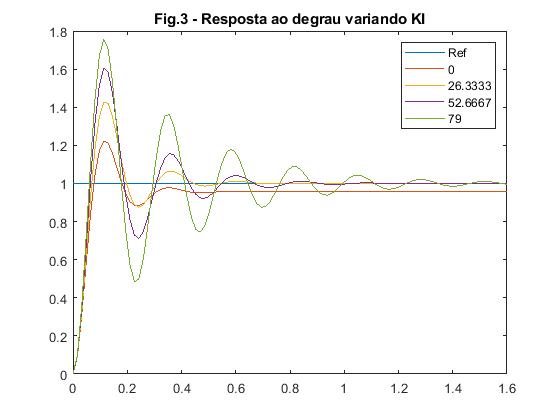

Tempo=1.6;
Y=[];
kimax=79;
C=pid(kp_s,0,0); 
K=linspace(0,kimax,10); 
t=linspace(0,Tempo,100)'; 
for i=1:length(K)
    C.Ki=K(i); 
    Gmf=feedback(C*G,1); 
    y=step(Gmf,t); 
    S=stepinfo(y,t); 
    Erro(i,1)=100*abs(1-y(end)); 
    UP(i,1)=S.Overshoot; 
    tempo_est(i,1)=S.SettlingTime; 
    tempo_sub(i,1)=S.RiseTime;    
    IAE(i)=trapz(t,abs(1-y));
    Y=[Y y]; 
end

figure;
plot(t,[ones(size(t)) Y(:,[1,4,7,10])]);title('Fig.3 - Resposta ao degrau variando KI');
legend('Ref',num2str(K(1)),num2str(K(4)),num2str(K(7)),num2str(K(10)));

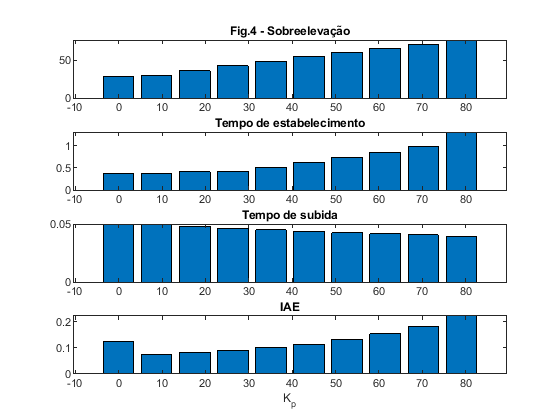


subplot(4,1,1);bar(K,UP);title('Fig.4 - Sobreelevação');
subplot(4,1,2);bar(K,tempo_est);title('Tempo de estabelecimento');
subplot(4,1,3);bar(K,tempo_sub);title('Tempo de subida');
subplot(4,1,4);bar(K,IAE);title('IAE');xlabel('K_p');

2.1 Qual o efeito do ganho Ki sobre a sobreelevação? Explique.

Ao analisar as figuras 3 e 4, vemos que quanto maior o Ki, temos um UP maior. Para o menor ganho, temos um UP de aprox. 20%. Para o maior ganho, temos um UP de aprox. 70%

2.2 Qual o efeito do ganho Ki sobre a tempo de estabelecimento? Justifique

Neste caso, vemos que o ki influencia no tempo de estabelecimento. Para o menor ganho, temos um tempo de estabelecimento de 0.4s,. e para o maior ganho, temos mais do que 1s.

2.3 Qual o efeito do ganho Ki sobre o IAE? Justifique

Analisando a figura 4, vemos que quanto maior o Ki, maior o IAE. Para Ki = 17.6, temos um valor de IAE de 0.08 e para Ki = 80, temos um IAE de 0.21

2.4 Comente o erro em regime observado, justificando

Vemos que para os menores ganhos de ki, temos um erro de regime maior. Basta olhar a figura 3 e analisar o fato de que o menor ganho tem um tempo de estabelecimento menor, mas o seu erro em regime é maior.

## Atividade 3 - Avaliação do efeito do ganho derivativo Kd

Escolher ki_s como sendo o valor tal que $UP\leq60$%. Escolher kdmax como sendo 1 ou um pouco menor.

Execute o script abaixo e responda as perguntas 3.1 a 3.3

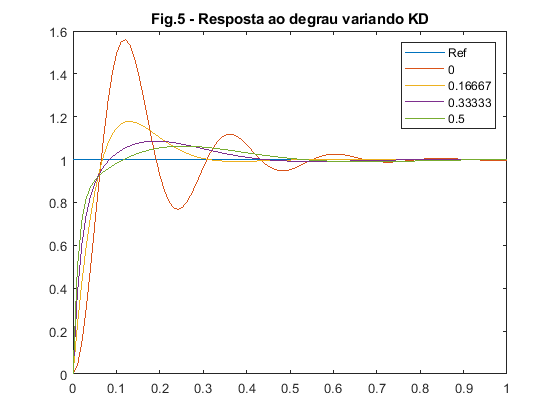

Tempo=1;
Y=[];
ki_s=45 ; 
kdmax= 0.5 ; 
C=pid(kp_s,ki_s,0);
K=linspace(0,kdmax,10);
t=linspace(0,Tempo,100)';

for i=1:length(K)
    C.Kd=K(i); 
    Gmf=feedback(C*G,1);
    y=step(Gmf,t);
    S=stepinfo(y,t); 
    Erro(i,1)=100*abs(1-y(end));
    UP(i,1)=S.Overshoot; 
    tempo_est(i,1)=S.SettlingTime; 
    tempo_sub(i,1)=S.RiseTime;   
    IAE(i)=trapz(t,abs(1-y));
    Y=[Y y]; 
end

figure;
plot(t,[ones(size(t)) Y(:,[1,4,7,10])]);title('Fig.5 - Resposta ao degrau variando KD');
legend('Ref',num2str(K(1)),num2str(K(4)),num2str(K(7)),num2str(K(10)));

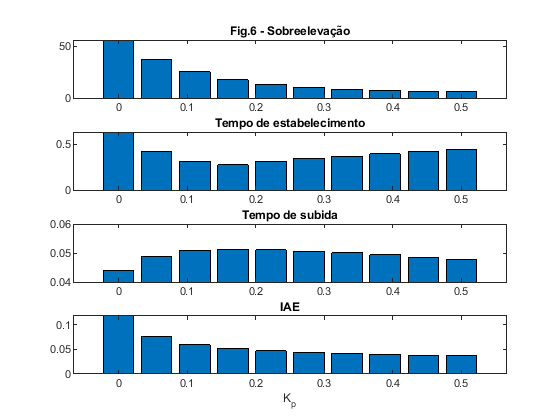


subplot(4,1,1);bar(K,UP);title('Fig.6 - Sobreelevação');
subplot(4,1,2);bar(K,tempo_est);title('Tempo de estabelecimento');
subplot(4,1,3);bar(K,tempo_sub);title('Tempo de subida');
ylim([0.04 0.06])
subplot(4,1,4);bar(K,IAE);title('IAE');xlabel('K_p');

3.1 Qual o efeito do ganho Kd sobre a sobreelevação? Explique.

Analisando as figuras 5 e 6, para kd = 0, temos um UP de mais de 50%. E para o kd = 0.5, o UP já beira valores menores que 10%. Portanto, concluímos que quanto maior o kd, menor o UP.

3.2 Qual o efeito do ganho Kd sobre o tempo de subida? Justifique

Para o kd = 0, vemos que o tempo de subida é de 0.043s e para o valor final de kd = 0.5, vemos que ele vai para 0.047s. Não é uma variação grande, mas como o kd 'freia/amortece' o sistema, é natural que ele faça aumentar um pouco o tempo de subida.

3.3 O Kd afeta o IAE? Como?

Sim. Ao aumentar os valores de kd, vemos que o IAE tende a diminuir.

## Atividade 4 - Seleção dos parametros do controlador PID

4.1 Baseado nas atividades e figuras mostradas, escolha os ganhos do controlador PID que dêem uma boa resposta, mostrando os ganhos e a resposta ao degrau correspondente. Justifique a escolha.

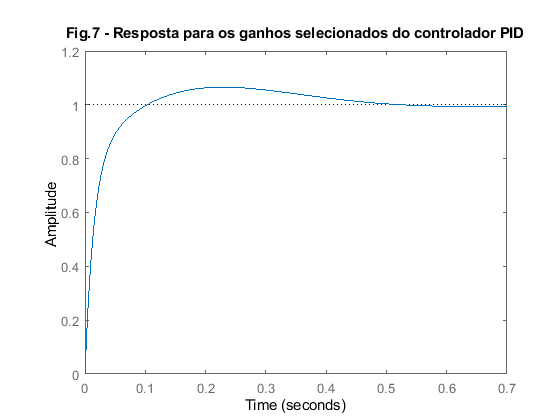

kp= 5.5;
ki= 40;
kd= 0.4;
C=pid(kp,ki,kd);
M=feedback(C*G,1);
figure;step(M);
title('Fig.7 - Resposta para os ganhos selecionados do controlador PID');

Justificando a escolha: Os valores de kp, ki e kd foram escolhidos de modo que a saída do sistema fosse a mais próxima da saída desejada. Ou seja, com um tempo rápido de subida, baixo overshoot, tempo de estabelecimento pequeno e um erro em regime nulo. Baseado nos gráficos e nas figuras anteriores e nos seus indicativos, estes valores de kp, ki e kd foram escolhidos para satisfazer as condições acima.

4.2 O script abaixo mostra o sinal de controle aplicado na atividade 4.1. Comente a necessidade de definir C.Tf e o valor máximo assumido pelo sinal de controle.

Resposta: O matlab não consegue simular se o sistema for impróprio (com mais zeros do que polos), então adicionamos um polo muito longe para que não tenha efeito no sistema, mas que deie a função do sistema própria.

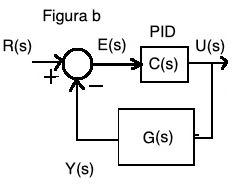

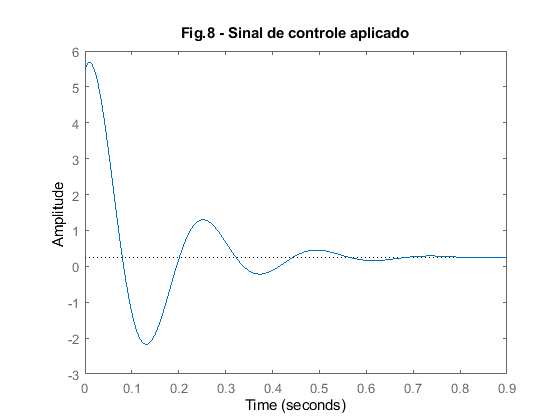

C.Tf=100;
Mru=feedback(C,G);
figure;step(Mru);title('Fig.8 - Sinal de controle aplicado')


datetime('now')

ans = datetime
   16-Jul-2021 19:46:54


pwd

ans = 'C:\Users\malaquias\Desktop\UFES\UFES-LCA\Original\Aula5'